% 一、求解析解
% 1.简单微分方程 y-y'=2x
ret = dsolve('y-Dy=2*x','y(0)=3','x');

% 可视化
x = -10:0.01:10;
y = 2*x + exp(x) + 2

y = 	1.0e+04 *

   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017


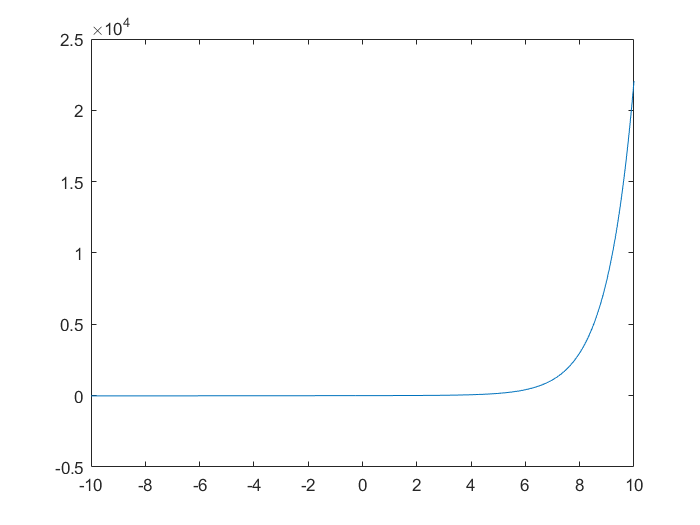

plot(x,y);


% 2.微分方程组

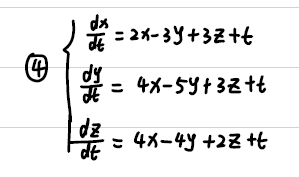

[x,y,z] = dsolve('Dx=2*x-3*y+3*z+t','Dy=4*x-5*y+3*z+t','Dz=4*x-4*y+2*z+t','t')

$$x = {\mathrm{e}}^{2\,t}\,\left(C_{3}-\frac{{\mathrm{e}}^{-2\,t}\,\left(2\,t+1\right)}{4}\right)+C_{1}\,{\mathrm{e}}^{-t}$$

$$y = {\mathrm{e}}^{2\,t}\,\left(C_{3}-\frac{{\mathrm{e}}^{-2\,t}\,\left(2\,t+1\right)}{4}\right)+C_{1}\,{\mathrm{e}}^{-t}+C_{2}\,{\mathrm{e}}^{-2\,t}$$

$$z = {\mathrm{e}}^{2\,t}\,\left(C_{3}-\frac{{\mathrm{e}}^{-2\,t}\,\left(2\,t+1\right)}{4}\right)+C_{2}\,{\mathrm{e}}^{-2\,t}$$

simplify(y)  % simplify函数可以简化表达式

$$ans = C_{1}\,{\mathrm{e}}^{-t}-\frac{t}{2}+C_{2}\,{\mathrm{e}}^{-2\,t}+C_{3}\,{\mathrm{e}}^{2\,t}-\frac{1}{4}$$

latex(y) % 转换成latex代码，复制到Axmath或者word自带的公式编辑器（低版本不知道支不支持）

ans = '{\mathrm{e}}^{2\,t}\,\left(C_{3}-\frac{{\mathrm{e}}^{-2\,t}\,\left(2\,t+1\right)}{4}\right)+C_{1}\,{\mathrm{e}}^{-t}+C_{2}\,{\mathrm{e}}^{-2\,t}'

% 二、求数值解
% 1.例题1

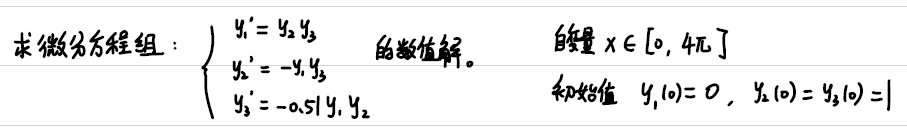

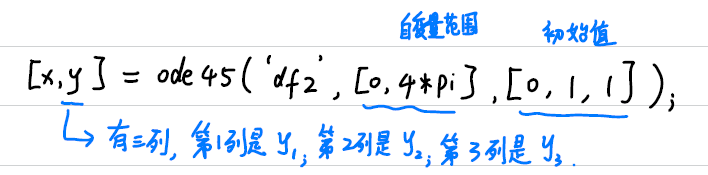

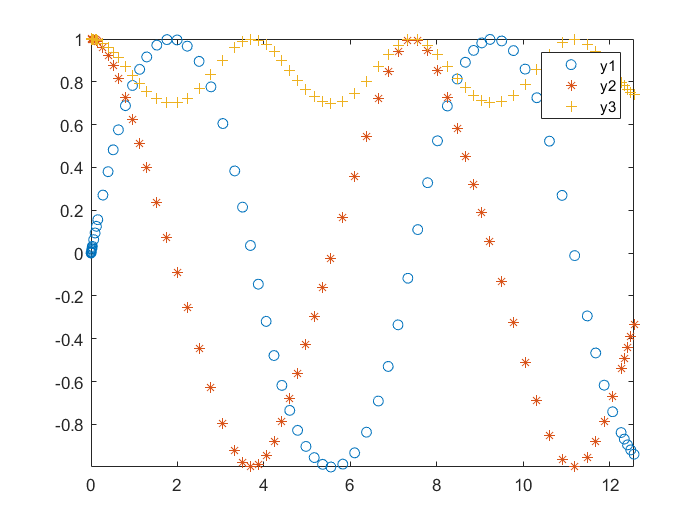

[x,y] = ode45('df1',[0,4*pi],[0,1,1]);

% 设定相对误差和绝对误差，这样可以提高微分方程数值解的精度
% options = odeset('reltol',1e-4,'abstol',1e-8);
% [x,y] = ode45('df1',[0,2],[0,1,1],options);
% 如果觉得x的间隔不够小，我们可以指定要求解的位置
% [x,y] = ode45('df1',[0:0.001:2],[0,1,1],options);

% 2.可视化
plot(x,y(:,1),'o',x,y(:,2),'*',x,y(:,3),'+')
legend('y1','y2','y3') % 显示图例
axis([0,4*pi,-inf,+inf]) % 设置横坐标和纵坐标范围

% 三、高阶微分方程求数值解
% 1.将高阶降为低阶

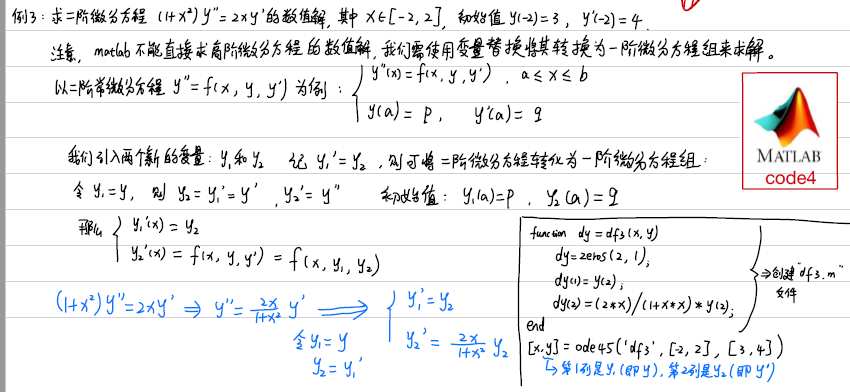


% 2.首先求是否有解析解
dsolve('(1+x*x)*D2y=2*x*Dy','y(-2)=3,Dy(-2)=4','x')

$$ans = \frac{4\,x\,\left(x^{2}+3\right)}{15}+\frac{101}{15}$$

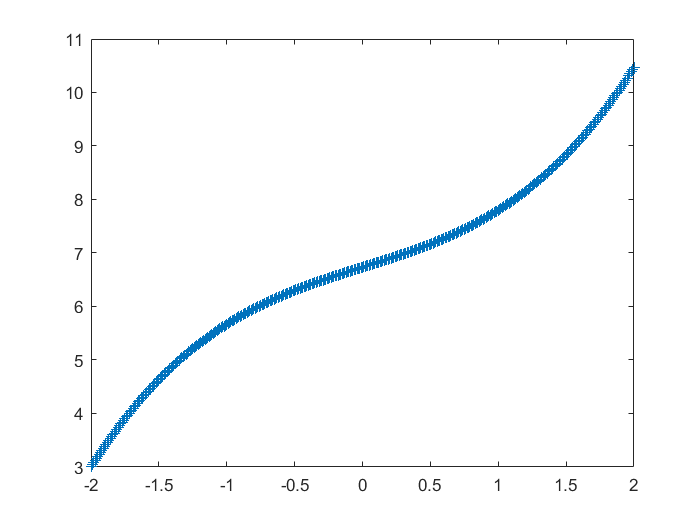

x = -2:0.01:2;
y = (4.*x.*(x.^2 + 3))./15 + sym(101/15);
plot(x,y,'+');

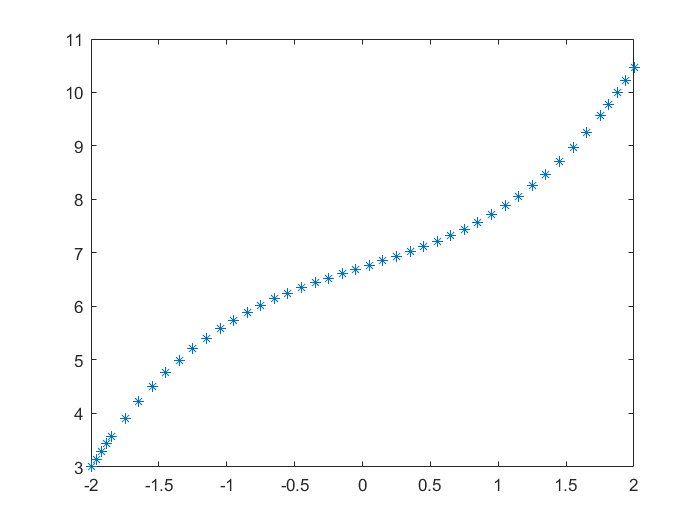

% 3.没有解析解求数值解

[x,y] = ode45('df2',[-2,2],[3,4]);
plot(x,y(:,1),'*')